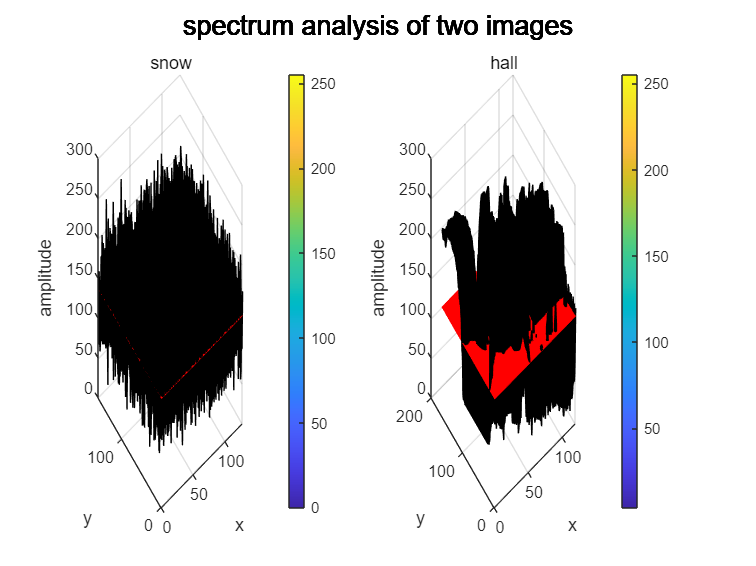

%freq_analysis.mlx
%analyze the frequency spectrum of two images.
load hall.mat;
load snow.mat;
dct_snow=dct2(snow);
dct_hall=dct2(hall_gray);

subplot(1,2,1);
plot_3D(snow);
title("snow");
subplot(1,2,2);
plot_3D(hall_gray);
title("hall");
sgtitle("spectrum analysis of two images");

function plot_3D(dat)
sz=size(dat);
mean_amp=mean(dat,"all");
[x,y]=meshgrid(1:1:sz(1),1:1:sz(2));

mean_surf=ones(sz).*mean_amp;
surf(x',y',dat); 
hold on
plot3(x',y',mean_surf,'Color','red');
colorbar;
hold off

xlabel("x");
ylabel("y");
zlabel("amplitude");
colorbar;
end